clear
load mnist_28.mat

save mnist_28.mat

%selecting and saving images to train
numE = 400;
validP = 0.25;
idx1 = (training.labels == 1);
place1 = find(cumsum(idx1) > numE-1);
idx2 = (training.labels == 2);
place2 = find(cumsum(idx2) > numE-1);
idx4 = (training.labels == 4);
place4 = find(cumsum(idx4) > numE-1);
idx8 = (training.labels == 8);
place8 = find(cumsum(idx8) > numE-1);
images1 = training.images(:,:,idx1(1:place1));
images2 = training.images(:,:,idx2(1:place2));
images4 = training.images(:,:,idx4(1:place4));
images8 = training.images(:,:,idx8(1:place8));
trainingImages = cat(3, images1(:,:,1:(numE*(1-validP))), images2(:,:,1:numE*(1-validP)), images4(:,:,1:numE*(1-validP)), images8(:,:,1:numE*(1-validP)));
validationImages = cat(3, images1(:,:,(numE*(1-validP)+1):numE), images2(:,:,(numE*(1-validP)+1):numE), images4(:,:,(numE*(1-validP)+1):numE), images8(:,:,(numE*(1-validP)+1):numE));

trainingImagesNoised = trainingImages - randn(28)/5

trainingImagesNoised = trainingImagesNoised(:,:,1) =

   -0.0456   -0.3386   -0.1913    0.2618   -0.4216    0.1570    0.0006    0.0091   -0.2772   -0.2255   -0.0662   -0.0745   -0.2652   -0.1020   -0.4945    0.0926    0.1177   -0.0570    0.1204    0.1313    0.0615   -0.2334   -0.1062   -0.2995   -0.0190    0.0746   -0.1756   -0.2128
   -0.0396    0.0974   -0.1709   -0.0869   -0.2370   -0.3196   -0.1597    0.2195    0.3269   -0.1500   -0.0096   -0.4193   -0.0091    0.2227   -0.4817   -0.0321   -0.1121    0.0462    0.0305   -0.0581    0.1160   -0.2152    0.0111   -0.4993    0.1490    0.2083   -0.0771   -0.0185
   -0.2108   -0.0612    0.2100   -0.1570   -0.0659    0.4560   -0.2939   -0.0468   -0.1208    0.1021    0.0671    0.3491   -0.1923    0.1163    0.1785    0.2600   -0.0899   -0.2610    0.0100   -0.3257    0.0305    0.0026    0.1777   -0.0012    0.0659   -0.0874    0.1749    0.3061
    0.1569    0.0240    0.0034   -0.1472   -0.1697    0.1252    0.2602   -0.2309   -0.0017    0.1685   

delete('trainingImages2\*')
for k = 1:size(trainingImagesNoised, 3)
    imwrite(trainingImagesNoised(:,:,k),"trainingImages2\image"+num2str(k)+".png");
end

validationImagesNoised = validationImages - randn(28)/5

validationImagesNoised = validationImagesNoised(:,:,1) =

   -0.1620    0.1596    0.0467    0.1021   -0.1501   -0.1207    0.3659    0.3198   -0.1647    0.2275   -0.2680    0.1876   -0.0947   -0.2214   -0.0590   -0.0794   -0.1964    0.6199   -0.6775    0.1118    0.0956    0.3279   -0.2161    0.1877   -0.2292   -0.1537   -0.2407   -0.3808
    0.0008   -0.0302   -0.1832    0.3124   -0.1136    0.2146    0.3565   -0.0702   -0.2656    0.0269   -0.0231    0.1637   -0.2409   -0.0559   -0.0341   -0.1775    0.0463   -0.1437    0.0110   -0.3918   -0.0328    0.5686    0.2057   -0.0210   -0.3271    0.1434    0.1882    0.0188
   -0.1480   -0.3472    0.0499   -0.1996   -0.1529   -0.1480    0.2587    0.1643    0.0900    0.1445   -0.3004   -0.0686    0.2414    0.2191    0.1315   -0.0355    0.1559   -0.2776    0.0680    0.0838    0.0343   -0.2974   -0.1725   -0.1674   -0.1995    0.1950   -0.1476   -0.3252
   -0.0476   -0.1063    0.1660    0.2063   -0.1518   -0.1163   -0.1317   -0.2478    0.0375   -0.061

delete('validationImages2\*')
for k = 1:size(validationImagesNoised, 3)
imwrite(validationImagesNoised(:,:,k),"validationImages2\image"+num2str(k)+".png");
end

%creating imagedatastore from the files
imds = imageDatastore("trainingImages2\");
valds = imageDatastore("validationImages2\");

%creating a pixellabeldatastore
ldc = labelDefinitionCreator();
addLabel(ldc,'on',labelType.PixelLabel);
addLabel(ldc,'off',labelType.PixelLabel);
labelDefs = create(ldc);
clear pixelLabelImages
pixelIdx = trainingImages ~= 0;
pixelLabelImages(28,28,1:size(trainingImages, 3)) = 0;
pixelLabelImages(pixelIdx) = 1;
pixelLabelImages(~pixelIdx) = 2;
pixelLabelImages = uint8(pixelLabelImages);
clear dataFile;
dataFile(size(trainingImages, 3),1) = "a";

delete('pixelLabelImages2\*')
for k = 1:size(trainingImages, 3)
    imwrite(pixelLabelImages(:,:,k),"pixelLabelImages2\image"+num2str(k)+".png");
    dataFile(k,1) = pwd+"\pixelLabelImages2\image"+num2str(k)+".png";
end


labelData = table(dataFile,'VariableNames',{'PixelLabelData'});
gtDataSource = groundTruthDataSource(imds);

gTruth = groundTruth(gtDataSource,labelDefs,labelData);
pxds = pixelLabelDatastore(gTruth);
pximds = combine(imds,pxds);

%doing the same thing for validation set
clear pixelLabelValImages
pixelValIdx = validationImages ~= 0;
pixelLabelValImages(28,28,1:size(validationImages, 3)) = 0;
pixelLabelValImages(pixelValIdx) = 1;
pixelLabelValImages(~pixelValIdx) = 2;
pixelLabelValImages = uint8(pixelLabelValImages);
clear dataFileVal;
dataFileVal(size(validationImages, 3),1) = "a";

delete('pixelLabelValImages2\*')
for k = 1:size(validationImages, 3)
    imwrite(pixelLabelValImages(:,:,k),"pixelLabelValImages2\image"+num2str(k)+".png");
    dataFileVal(k,1) = pwd+"\pixelLabelValImages2\image"+num2str(k)+".png";
end

labelDataVal = table(dataFileVal,'VariableNames',{'PixelLabelData'});
gtDataSourceVal = groundTruthDataSource(valds);
gTruthVal = groundTruth(gtDataSourceVal,labelDefs,labelDataVal);
pxdsVal = pixelLabelDatastore(gTruthVal);
pximdsVal = combine(valds,pxdsVal);

%creating encoder decoder structure
encoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate*2,"Padding",'same')
    batchNormalizationLayer
    reluLayer("Name","db"+num2str(inputDepth))];
decoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth-growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer];

layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    encoderBlock(16,32)
    maxPooling2dLayer(2,"Stride",2)
    encoderBlock(32,64)
    maxPooling2dLayer(2,"Stride",2)
    convolution2dLayer(3, 128, Padding="same")
    reluLayer
    convolution2dLayer(3, 256, Padding="same")
    reluLayer
    transposedConv2dLayer(2,128,"Stride",2, "Name", "up1")
    depthConcatenationLayer(2)
    decoderBlock(64, 128)
    transposedConv2dLayer(2,64,"Stride",2, "Name","up2")
    depthConcatenationLayer(2)
    decoderBlock(32,64)
    convolution2dLayer(3, 16, Padding="same")
    reluLayer
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    convolution2dLayer(3, 2, Padding="same")
    softmaxLayer
    pixelClassificationLayer
];


%setting training options
options = trainingOptions( ...
'adam',...
'MiniBatchSize', 400,...
'MaxEpochs',3000, ...
'Plots', 'training-progress', ...
'ValidationData', pximdsVal, ...
'ValidationFrequency',20, ...
'ValidationPatience',10);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       37.98% |       79.23% |       0.8258 |       0.5266 |          0.0010 |
|       5 |          20 |       00:03:03 |       85.30% |       83.71% |       0.2886 |       0.3065 |          0.0010 |
|      10 |          40 |       00:06:25 |       85.93% |       83.84% |       0.2788 |       0.3095 |          0.0010 |
|      13 |          50 |       00:08:11 |       86.15% |              |       0.2742 |              |          0.0010 |
|      1

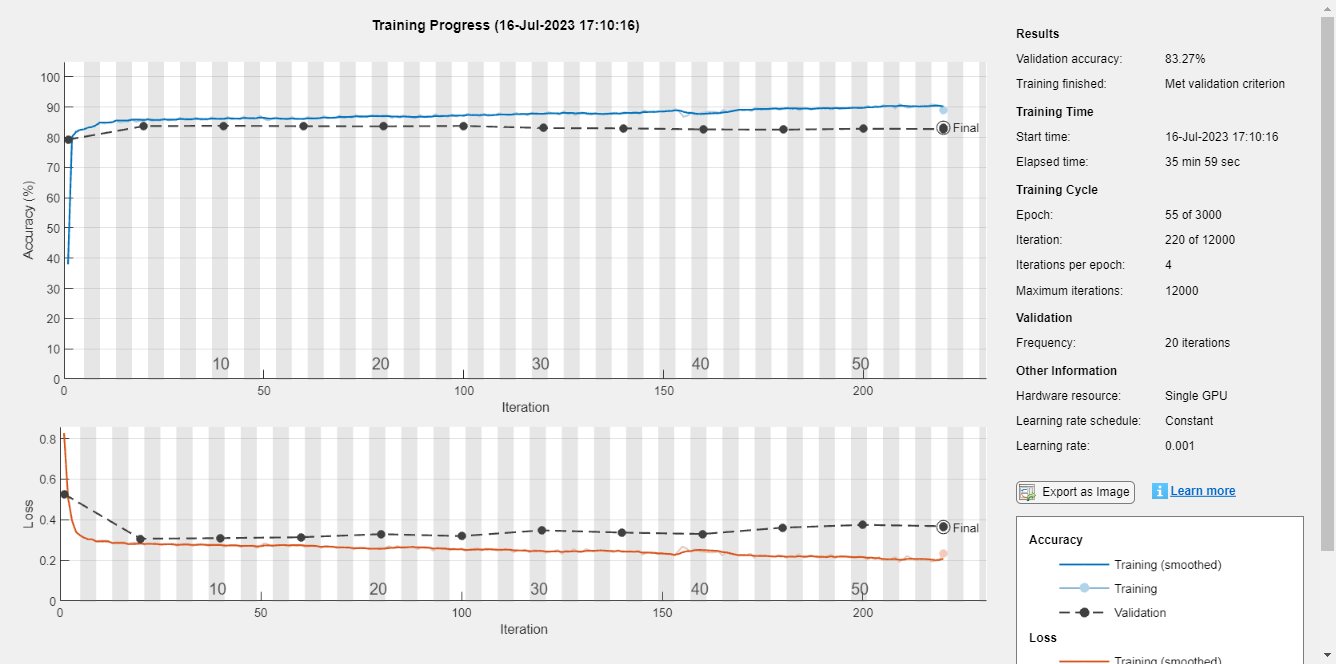

net =   DAGNetwork with properties:

         Layers: [51×1 nnet.cnn.layer.Layer]
    Connections: [52×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


%training net
net =  trainNetwork(pximds, lgraph_2, options)

save mnist_28.mat

% %test code
% for k=1:12
%     idx = 1;
%     trueCheck = 0;
%     while trueCheck ~= 1
%     idx = randi(size(test.images,3));
%     if test.labels(idx) == (4)
%         trueCheck = 1;
%     end  
%     end
%     subplot(2,12,k)
%     imshow(test.images(:,:,idx)*255)
%     title("ground "+num2str(idx))
%     subplot(2,12,k+12)
%     prediction = predict(net,test.images(:,:,idx)*255);
%     imshow(prediction(:,:,1))
%     title("prediction "+num2str(idx))
% end

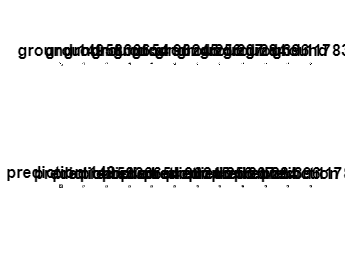

for k=1:12
    idx = randi(size(validationImagesNoised,3));
    subplot(2,12,k)
    imshow(validationImagesNoised(:,:,idx)*255)
    title("ground "+num2str(idx))
    subplot(2,12,k+12)
    prediction = predict(net,validationImagesNoised(:,:,idx)*255);
    imshow(prediction(:,:,1))
    title("prediction "+num2str(idx))
end